# **Chapter 19 Mini Quiz (Q1)**

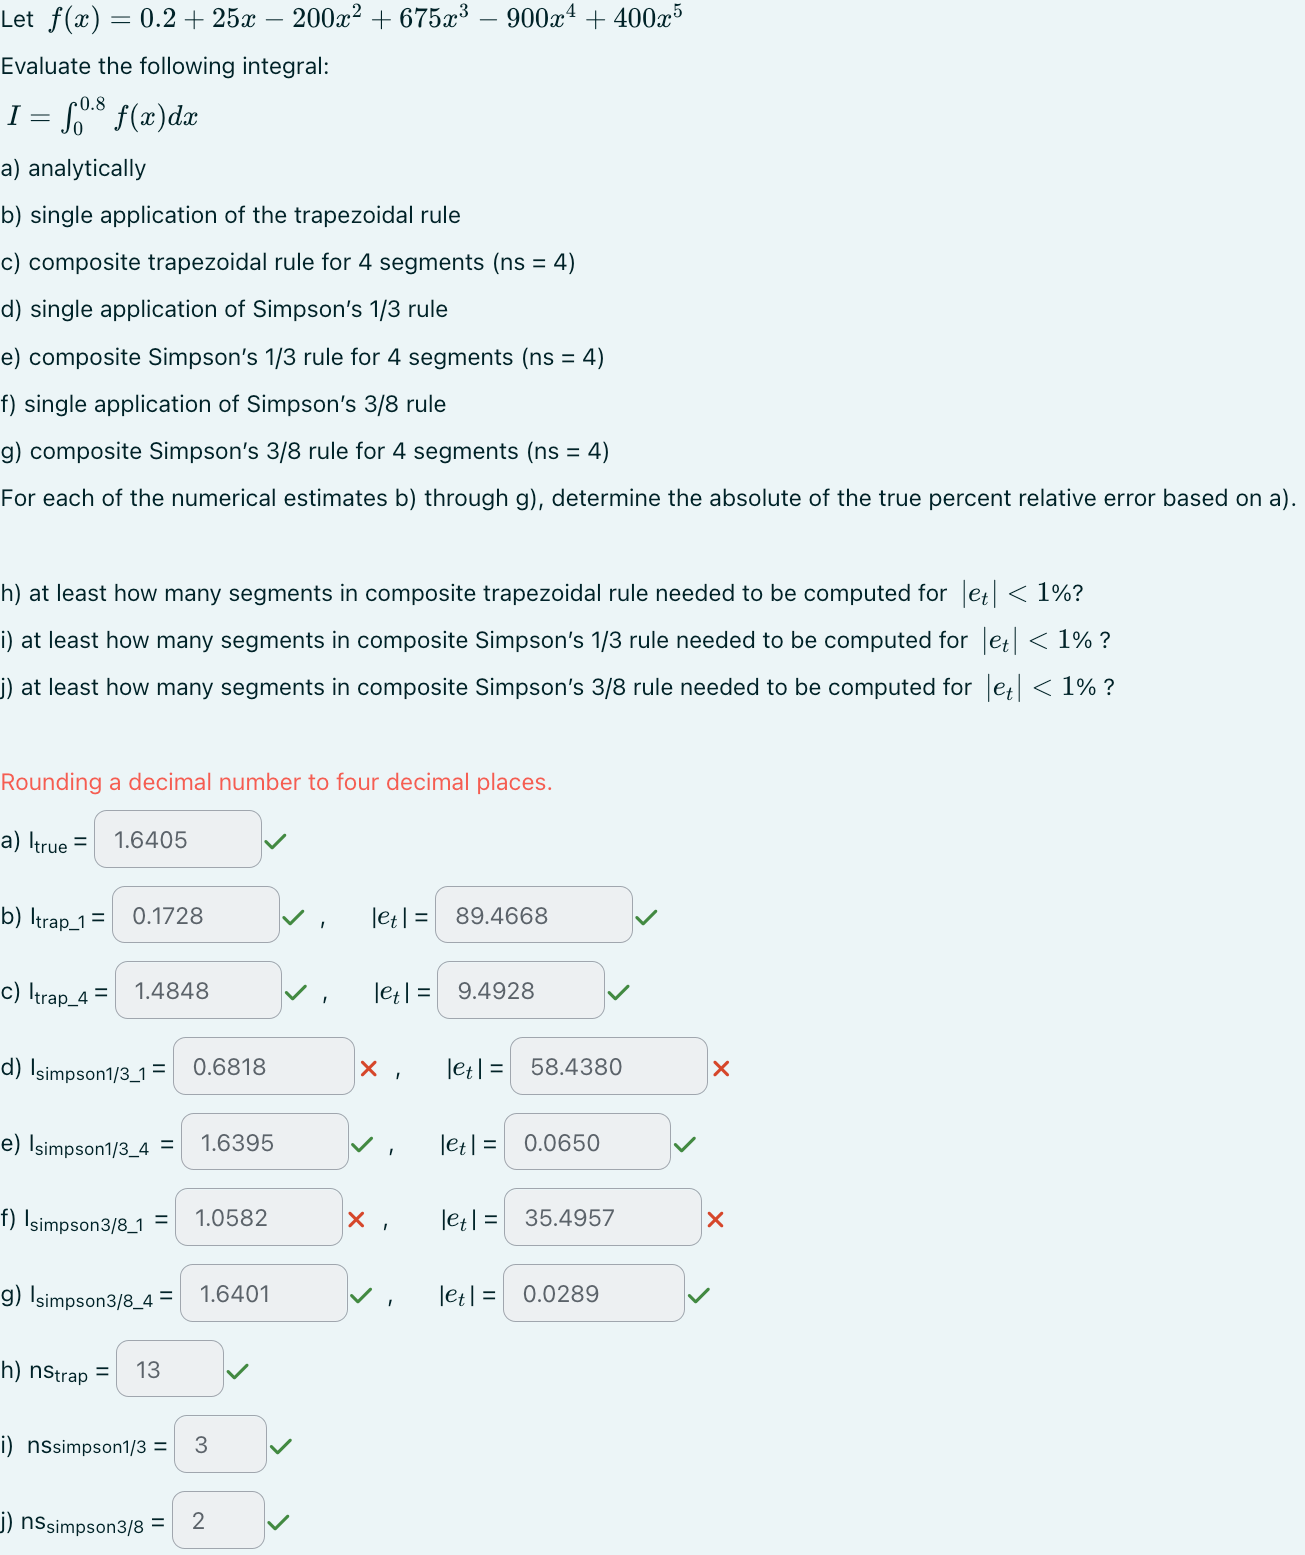

Function

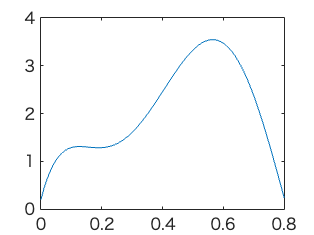

f=@(x) 400.*x.^5 - 900.*x.^4 + 675.*x.^3 - 200.*x.^2 + 25.*x + 0.2;

xx = 0 : 0.01 : 0.8;
yy = f(xx);

plot(xx, yy, '-')

To integrate function from 0 to 0.8 *(doing analytical integration)*

format short
a = 0;
b = 0.8;
p = [400 -900 675 -200 25 0.2];
q = polyint(p); % integrate polynomial equation (gives us the EXACT integration)
Itrue = diff(polyval(q, [a, b])) % for relative value (this is from `polyint` help page)

Itrue = 1.6405

Plot original function along with trapezoidal rule ns = 1 (single application)

ns = 1

ns = 1


% NEW
I_trap_ns1 = trap(f, a, b, ns)

I_trap_ns1 = 0.1728

err_ns1 = ((Itrue - I_trap_ns1) / Itrue) * 100

err_ns1 = 89.4668

Plot original function along with trapezoidal rule ns = 4

ns = 4

ns = 4


% NEW
I_trap_ns4 = trap(f, a, b, ns)

I_trap_ns4 = 1.4848

err_ns4 = ((Itrue - I_trap_ns4) / Itrue) * 100

err_ns4 = 9.4928

Single application of Simpson’s 1/3 rule (ns = 1)

y = f(x);

% NEW
h = (b - a) / 2

h = 0.4000

I_simpson13_ns1 = (h/3) * (y(1) + 4*y(2) + y(3)) % formula from the slides (page 18)

I_simpson13_ns1 = 0.6818

err_simpson13_ns1 = ((Itrue - I_simpson13_ns1) / Itrue) * 100

err_simpson13_ns1 = 58.4380

# **TODO: VERIFY CODE IN THIS SECTION**

Composite Simpson’s 1/3 rule for 4 segments (ns = 4)

ns = 4

ns = 4

h  = (b - a)/(2*ns); % basically step size
simpson13_ns4 = zeros(1,ns);            % pre-allocate area for each segment

for i = 1:ns
    x0 = a + 2*(i-1)*h;                 % left end of current segment
    simpson13_ns4(i) = (h/3)*( ...
        f(x0)        + ...              % f(x₀)
        4*f(x0 + h)  + ...              % 4 f(x₀ + h)
        f(x0 + 2*h) );                  % f(x₀ + 2h)
end

% total integral and relative error
I_simpson13_ns4  = sum(simpson13_ns4)

I_simpson13_ns4 = 1.6395

err_simpson13_ns4 = ((Itrue - I_simpson13_ns4)/Itrue)*100

err_simpson13_ns4 = 0.0650

Single application of Simpson’s 3/8 rule (ns = 1)

ns = 1

ns = 1

y = f(x);

% NEW
h = (b - a) / 3

h = 0.2667

I_simpson38_ns1 = (3*h/8) * (y(1) + 3*y(2) + 3*y(3) + 3*y(4)) % formula from the slides (page 18)

I_simpson38_ns1 = 1.0582

err_simpson38_ns1 = ((Itrue - I_simpson38_ns1) / Itrue) * 100

err_simpson38_ns1 = 35.4957

Composite Simpson’s 3/8 rule for 4 segments (ns = 4)

%% FINISHED CODE — Composite Simpson 3/8 with ns = 4 segments
ns = 4;                                 % number of Simpson-3/8 segments
h  = (b - a)/(3*ns);                    % step size  (3 sub-intervals per segment)

simpson38_ns4 = zeros(1,ns);            % pre-allocate area for each segment
for i = 1:ns
    x0 = a + 3*(i-1)*h;                 % left end of current segment
    simpson38_ns4(i) = (3*h/8)*( ...
        f(x0)          + ...            % f(x₀)
        3*f(x0 +   h)  + ...            % 3·f(x₀+h)
        3*f(x0 + 2*h)  + ...            % 3·f(x₀+2h)
        f(x0 + 3*h) );                  % f(x₀+3h)
end

% total integral and relative error
I_simpson38_ns4  = sum(simpson38_ns4)

I_simpson38_ns4 = 1.6401

err_simpson38_ns4 = ((Itrue - I_simpson38_ns4)/Itrue)*100

err_simpson38_ns4 = 0.0289

At least how many segments in composite trapezoidal rule needed to be computed for |$e_t$| < 1%?

ns = 13

ns = 13

I_trap_ns = trap(f, a, b, ns)

I_trap_ns = 1.6254

err_ns = ((Itrue - I_trap_ns) / Itrue) * 100

err_ns = 0.9210

At least how many segments in composite Simpson’s 1/3 rule needed to be computed for |$e_t$| < 1%?

ns = 3

ns = 3

h  = (b - a)/(2*ns); % basically step size
simpson13_ns = zeros(1,ns);            % pre-allocate area for each segment

for i = 1:ns
    x0 = a + 2*(i-1)*h;                 % left end of current segment
    simpson13_ns(i) = (h/3)*( ...
        f(x0)        + ...              % f(x₀)
        4*f(x0 + h)  + ...              % 4 f(x₀ + h)
        f(x0 + 2*h) );                  % f(x₀ + 2h)
end

% total integral and relative error
I_simpson13_ns = sum(simpson13_ns);
err_simpson13_ns = ((Itrue - I_simpson13_ns)/Itrue)*100

err_simpson13_ns = 0.2055

At least how many segments in composite Simpson’s 3/8 rule needed to be computed for |$e_t$| < 1%?

ns = 2                                 % number of Simpson-3/8 segments
h  = (b - a)/(3*ns);                    % step size  (3 sub-intervals per segment)

simpson38_ns = zeros(1,ns);            % pre-allocate area for each segment
for i = 1:ns
    x0 = a + 3*(i-1)*h;                 % left end of current segment
    simpson38_ns(i) = (3*h/8)*( ...
        f(x0)          + ...            % f(x₀)
        3*f(x0 +   h)  + ...            % 3·f(x₀+h)
        3*f(x0 + 2*h)  + ...            % 3·f(x₀+2h)
        f(x0 + 3*h) );                  % f(x₀+3h)
end

% total integral and relative error
I_simpson38_ns = sum(simpson38_ns);
err_simpson38_ns4 = ((Itrue - I_simpson38_ns)/Itrue)*100

err_simpson38_ns4 = 0.4624